# Essentials of Deep Learning

In this project, we learn and play essential mathematical components of deep learning on a simple artificial neural network by using the MATLAB script provided by C. F. Higham and D. J. Higham along with their paper ''Deep Learning: An Introduction for Applied Mathematicians'', arXiv:1801.05894v1, Jan. 2018. Minor changes have been made to the original script.

## Set up the training data

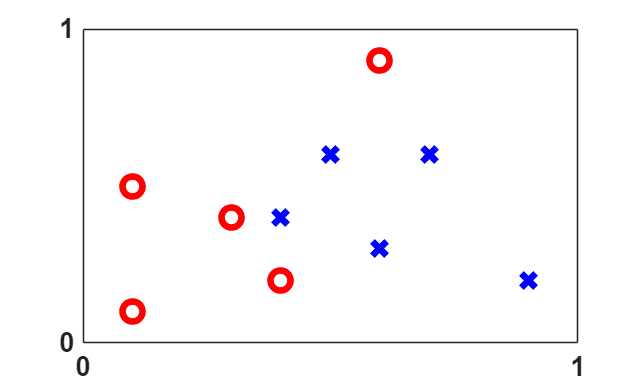

addpath("./Code")

% Initial training data 
m = 5; 
n = 5; 
x1 = [0.1,0.3,0.1,0.6,0.4,0.6,0.5,0.9,0.4,0.7]; 
x2 = [0.1,0.4,0.5,0.9,0.2,0.3,0.6,0.2,0.4,0.6]; 
y = [ones(1,m) zeros(1,n); zeros(1,m) ones(1,n)]; 

% Plot the training data 
figure(2) 
clf 
a1 = subplot(1,1,1); 
plot(x1(1:m),x2(1:m),'ro','MarkerSize',12,'LineWidth',4) 
hold on 
plot(x1(m+1:m+n),x2(m+1:m+n),'bx','MarkerSize',12,'LineWidth',4) 
a1.XTick = [0 1]; 
a1.YTick = [0 1]; 
a1.FontWeight = 'Bold'; 
a1.FontSize = 16; 
xlim([0,1]) 
ylim([0,1])

## Expressions of backpropagation and stochastic gradient descent

Consider a network with L layers, where each layer contains a single neuron. The input and output of each layer are scalars, except for the first input vector $x$.

Let's construct the network with the following notation: $X$ is the input, $y$ is the output and for every layer $i=2,3,\dots ,L$


$$z_i = w_ia_{i-1}+b_i$$



$$a_i = \sigma(z_i)$$


With $\sigma$ being the activation function, $w_i$ and $b_i$ being the weight and bias of layer $i$. In this case, all $w_i$ and $b_i$ are scalars. Note that $\hat y = a_L$.

For layer 1, we have:


$$z_1 = w_1x+b_1 \text{ and } a_1 = \sigma(z_1)$$


With $w_1$ and $b_1$, being vectors.

The corresponding derivatives used in backpropagation are:


$$\frac{\partial L}{\partial w_L}=\frac{\partial L}{\partial z_L}\frac{\partial z_L}{\partial w_L} = a_{L-1} (\hat y-y)$$



$$\frac{\partial L}{\partial b_L}=\frac{\partial L}{\partial z_L}\frac{\partial z_L}{\partial b_L} = \hat y-y$$


For all $i=2,3, \dots ,L-1$


$$\frac{\partial L}{\partial w_i}=\frac{\partial L}{\partial z_i}\frac{\partial z_i}{\partial w_i} = \delta_ia_i$$



$$\frac{\partial L}{\partial b_i}=\frac{\partial L}{\partial z_i}\frac{\partial z_i}{\partial b_i} =\delta_i$$



$$\delta_i = \frac{\partial L}{\partial z_i}=\frac{\partial L}{\partial z_{i+1}}\frac{\partial z_{i+1}}{\partial z_i} = \delta_{i+1} \frac{\partial\big(w_{i+1}\sigma(z_i)+b_i\big )}{\partial z_i} = \delta_{i+1} w_{i+1}\sigma'(z_i)$$


For layer 1, $x$, $w_1$ and $b_1$ are vectors:


$$\frac{\partial L}{\partial w_1}=\frac{\partial L}{\partial z_1}\frac{\partial z_1}{\partial w_1} = \delta_1x^T$$



$$\frac{\partial L}{\partial b_1}=\frac{\partial L}{\partial z_1}\frac{\partial z_1}{\partial b_1} =\delta_1$$



$$\frac{\partial L}{x}=\frac{\partial L}{\partial z_1}\frac{\partial z_1}{\partial x} = \delta_1 \frac{\partial\big(w_1x+b_1\big )}{\partial x} = \delta_1 w_1^T\sigma'(z_1)$$


## Training

We test several architectures using sigmoid and ReLu activations.

First, we construct a network of 4 layers with respectively 2, 2, 3 and 2 neurons each in combined with sigmoid activation. The parameters are kept as follows: 

Total training time: 3.4511


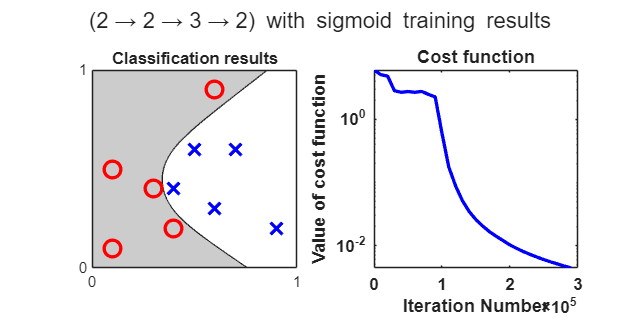

eta = 0.05; % learning rate
Niter = 3e5; % total number of iterations, adjustable to your computational budget
[X,Y,Mval,savecost] = net_2_2_3_2_sig(m,n,x1,x2,y,eta,Niter);

For the first model, training converges correctly, classifying the two groups.

The second model is a network of 5 layers with respectively 2, 5, 5, 5 and 2 neurons each still combined with sigmoid activation function. We keep the same learning rate and number iteration as above.

Total training time: 4.1684


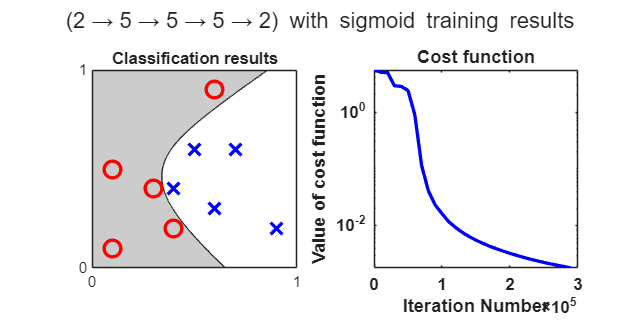

[X,Y,Mval,savecost] = net_2_5_5_5_2_sig(m, n, x1, x2, y, eta, Niter);

The deeper model converges faster and achieves similar accuracy to the first network, indicating improved optimization stability.

To construct the third model, we change activation function of model 1 into ReLu activation function for every layer and choose a learning rate equal to 0.0025.

Total training time: 2.6339


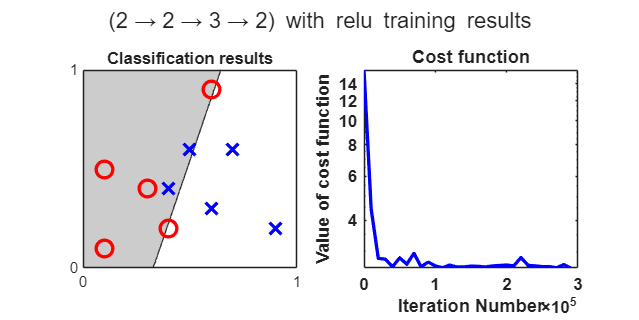

eta = 0.0025; % learning rate
Niter = 3e5; % total number of iterations, adjustable to your computational budget
[X,Y,Mval,savecost] = net_2_2_3_2_relu(m, n, x1, x2, y, eta, Niter);

The third model fails to correctly classify the data. The ReLu activation introduces non-linearity, but with too few neurons or layers, the network behaves almost linearly. This highlights the importance of model capacity when using piecewise-linear activations.

The fourth model is the combination of the second one (2-5-5-5-2) and the relu activation function. For this model, we choose a learning rate equal to 0.0025

Total training time: 3.5339


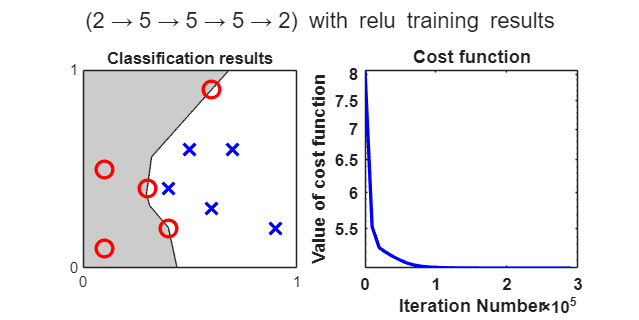

[X,Y,Mval,savecost] = net_2_5_5_5_2_relu(m, n, x1, x2, y, eta, Niter);

This last model succeeds in classifying the data despite some points that are at the limits of their class. In terms of convergence, this model is better than the first one. Indeed, the convergence is faster and can be considered as optimal for a number of  iterations equals to $10^5$.

## Behaviour on more complex dataset

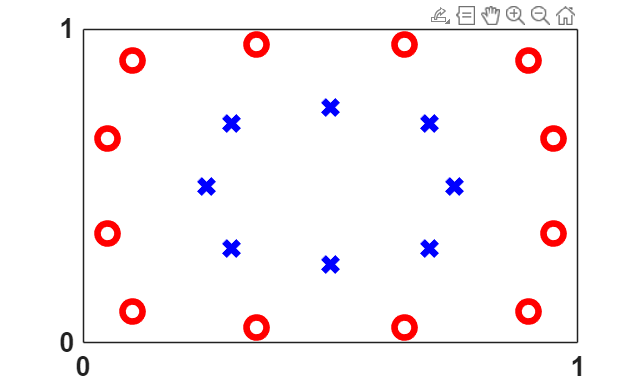

% Initialize training data
m = 12; 
n = 8; 
x1 = [0.1,0.05,0.05,0.1,0.35,0.65,0.9,0.95,0.95,0.9,0.65,0.35,0.7,0.3,0.3,0.7,0.25,0.75,0.5,0.5]; 
x2 = [0.1,0.65,0.35,0.9,0.95,0.95,0.9,0.65,0.35,0.1,0.05,0.05,0.7,0.7,0.3,0.3,0.5,0.5,0.75,0.25]; 
y = [ones(1,m) zeros(1,n); zeros(1,m) ones(1,n)]; 
y = [ones(1,m) zeros(1,n); zeros(1,m) ones(1,n)];

% Plot the training data 
figure(2) 
clf 
a1 = subplot(1,1,1); 
plot(x1(1:m),x2(1:m),'ro','MarkerSize',12,'LineWidth',4) 
hold on 
plot(x1(m+1:m+n),x2(m+1:m+n),'bx','MarkerSize',12,'LineWidth',4) 
a1.XTick = [0 1]; 
a1.YTick = [0 1]; 
a1.FontWeight = 'Bold'; 
a1.FontSize = 16; 
xlim([0,1]) 
ylim([0,1])

To test further the models, we use this more complex dataset of points.

Total training time: 6.5732


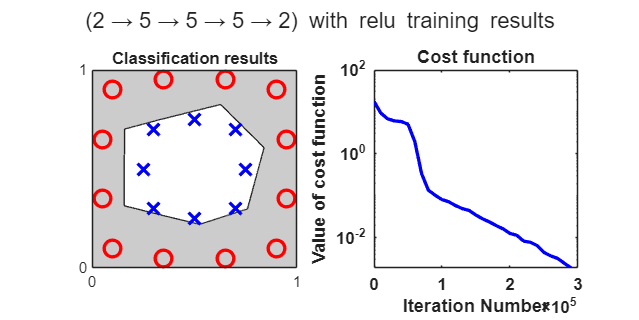

eta = 0.0025; % learning rate
Niter = 3e5; % total number of iterations, adjustable to your computational budget
[X,Y,Mval,savecost] = net_2_5_5_5_2_relu(m, n, x1, x2, y, eta, Niter);

Whereas the first models fail to return a valid separation line, the last network (2-5-5-5-2 + ReLu) works pretty well on this data. The network successfully learns non-linear class boundaries and generalizes well to more challenging patterns.